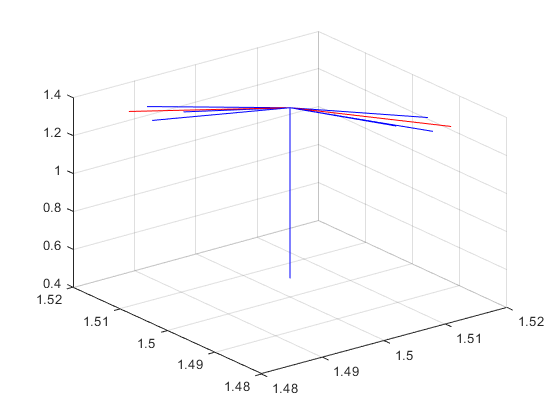

P_led = [1.5 1.5 3];  %LED的位置
P_pd = [1.5 1.5 0.5]; 
Angle_Dev = 0;   %偏移角度
Angle_Rot = 2*pi/3;   %旋转角度
Vector_reference = P_led - P_pd ; %Vector from PD to LED, the final vectors we need is three vectors around it.
Vector_reference = Vector_reference/norm(Vector_reference,2);
Angle_ref = atan(Vector_reference(3)/sqrt(Vector_reference(1)^2+Vector_reference(2)^2)); %angle between reference vector and ground
Angle_v1 = Angle_ref - Angle_Dev; %angle between facing vector1 and ground
if Angle_ref == pi/2
    Fvector(1,1) =  cos(Angle_v1);
    Fvector(1,2) =  0;
    Fvector(1,3) =  sin(Angle_v1);

else   
    Fvector(1,1) =  Vector_reference(1)*cos(Angle_v1)/sqrt(Vector_reference(1)^2+Vector_reference(2)^2);
    Fvector(1,2) =  Vector_reference(2)*cos(Angle_v1)/sqrt(Vector_reference(1)^2+Vector_reference(2)^2);
    Fvector(1,3) =  sin(Angle_v1);
end
Fvector(2,:) = cos(Angle_Rot)*Fvector(1,:) + (1-cos(Angle_Rot))*dot(Vector_reference,Fvector(1,:))*Vector_reference + sin(Angle_Rot)*(cross(Vector_reference,Fvector(1,:)));
Fvector(3,:) = cos(2*Angle_Rot)*Fvector(1,:) + (1-cos(2*Angle_Rot))*dot(Vector_reference,Fvector(1,:))*Vector_reference + sin(2*Angle_Rot)*(cross(Vector_reference,Fvector(1,:)));  
% Fvector(2,:) = cos(2*pi/3)*Fvector(1,:) + (1-cos(2*pi/3))*dot(Vector_reference,Fvector(1,:))*Vector_reference + sin(2*pi/3)*(cross(Vector_reference,Fvector(1,:)));
% Fvector(3,:) = cos(4*pi/3)*Fvector(1,:) + (1-cos(4*pi/3))*dot(Vector_reference,Fvector(1,:))*Vector_reference + sin(4*pi/3)*(cross(Vector_reference,Fvector(1,:)));


quiver3(P_pd(1),P_pd(2),P_pd(3),Vector_reference(1),Vector_reference(2),Vector_reference(3),'r')
hold on
quiver3(P_pd(1),P_pd(2),P_pd(3),Fvector(1,1),Fvector(1,2),Fvector(1,3),'b')
hold on
quiver3(P_pd(1),P_pd(2),P_pd(3),Fvector(2,1),Fvector(2,2),Fvector(2,3),'b')
hold on
quiver3(P_pd(1),P_pd(2),P_pd(3),Fvector(3,1),Fvector(3,2),Fvector(3,3),'b')
hold off